# Comparison of Mortality across Countries

## Import data on mortality in Switzerland

opts = spreadsheetImportOptions("NumVariables", 13);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A4:M63";

% Specify column names and types
opts.VariableNames = ["Year", "Population_gy", "Deaths_gy", "LifeExpecancy_gy", "Population_sl", "Deaths_sl", "LifeExpecancy_sl", "Population_sd", "Deaths_sd", "LifeExpecancy_sd", "Population_sn", "Deaths_sn", "LifeExpecancy_sn"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
countrycomparison = readtable("country_comparison.xlsx", opts, "UseExcel", false)

countrycomparison = 60×13 table
    Year    Population_gy    Deaths_gy     LifeExpecancy_gy    Population_sl    Deaths_sl     LifeExpecancy_sl    Population_sd    Deaths_sd    LifeExpecancy_sd    Population_sn    Deaths_sn    LifeExpecancy_sn
    ____    _____________    __________    ________________    _____________    __________    ________________    _____________    _________    ________________    _____________    _________    ________________

    1960     7.3414e+07      8.7672e+05         69.33           3.2068e+06      8.3449e+07          NaN

clear opts

## Store data in a usable format

time = table2array(countrycomparison(:,1));
myTime = time(end - 19:end)

myTime =         2000
        2001
        2002
        2003
        2004
        2005
        2006
        2007
        2008
        2009



germany = table2array(countrycomparison(:, 2:4));
senegal = table2array(countrycomparison(:, 5:6));
switzerland = table2array(countrycomparison(:, 8:10));
sweden = table2array(countrycomparison(:, 11:13));

## Compare total deaths across countries

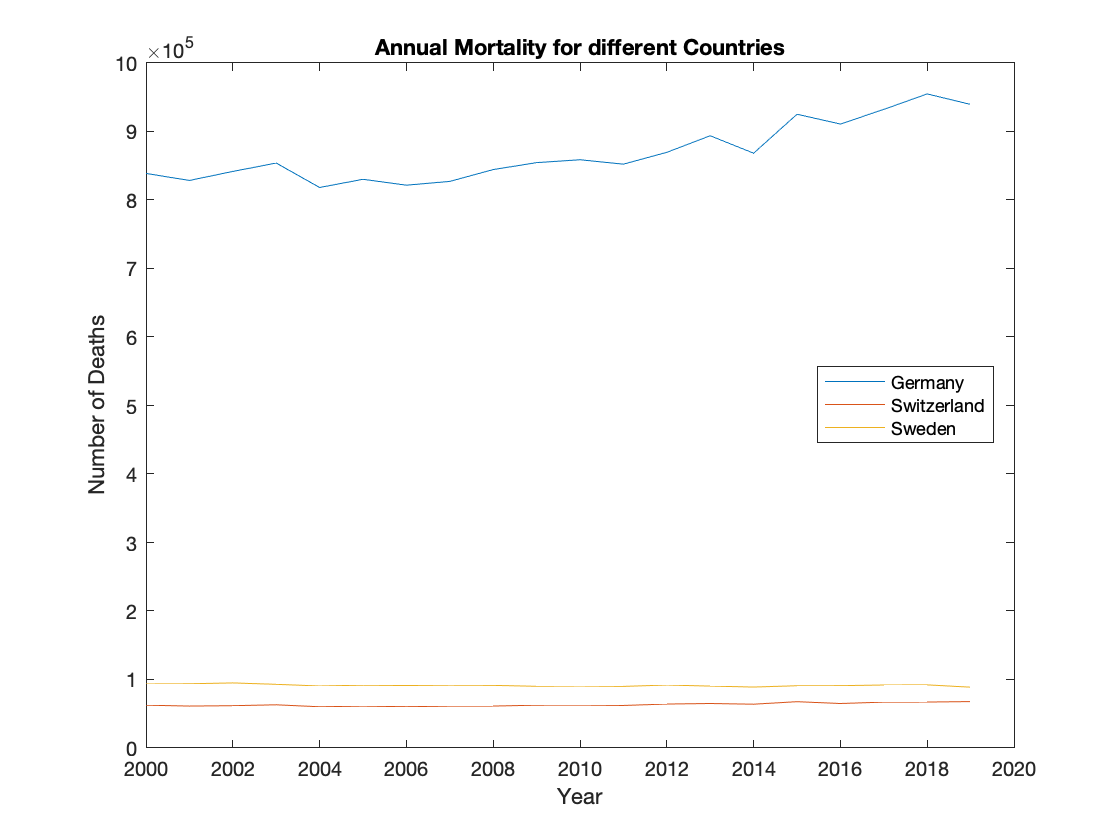

plot(myTime, germany(end - 19:end,2));
hold on

% plot(myTime, senegal(end - 19:end,2));
plot(myTime, switzerland(end - 19:end, 2));
plot(myTime, sweden(end - 19:end,2));

title('Annual Mortality for different Countries')

xlabel('Year')
ylabel('Number of Deaths')

legend('Germany', 'Switzerland', 'Sweden', 'Location', 'best')
hold off

## Compare total deaths across countries

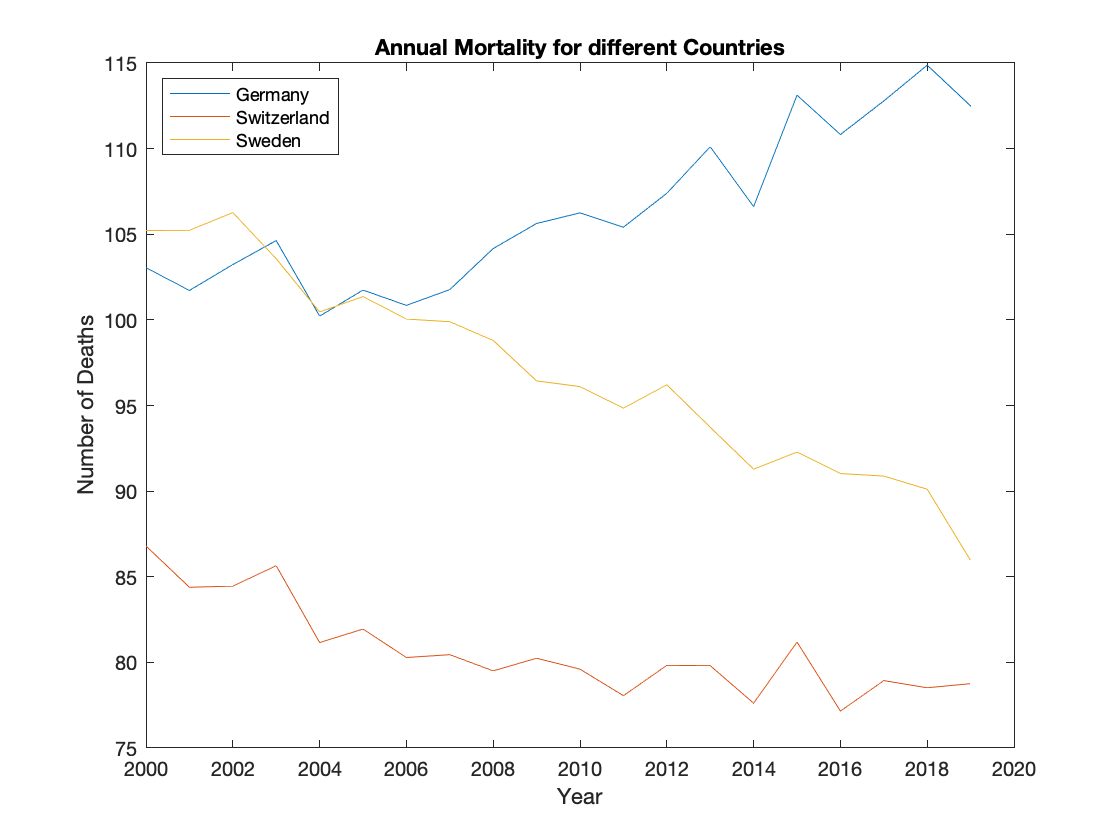

norm_germany = germany(:,2) ./ germany(:,1) .* 10000;
norm_senegal = senegal(:,2) ./ senegal(:,1) .* 10000;
norm_switzerland = switzerland(:,2) ./ switzerland(:,1) .* 10000;
norm_sweden = sweden(:,2) ./ sweden(:,1) .* 10000;


plot(myTime, norm_germany(end - 19:end));
hold on

% plot(myTime, norm_senegal(end - 19:end));
plot(myTime, norm_switzerland(end - 19:end));
plot(myTime, norm_sweden(end - 19:end));

title('Annual Mortality for different Countries')

xlabel('Year')
ylabel('Number of Deaths')

legend('Germany', 'Switzerland', 'Sweden', 'Location', 'northwest')
hold off